# Post-Hoc Power Analysis

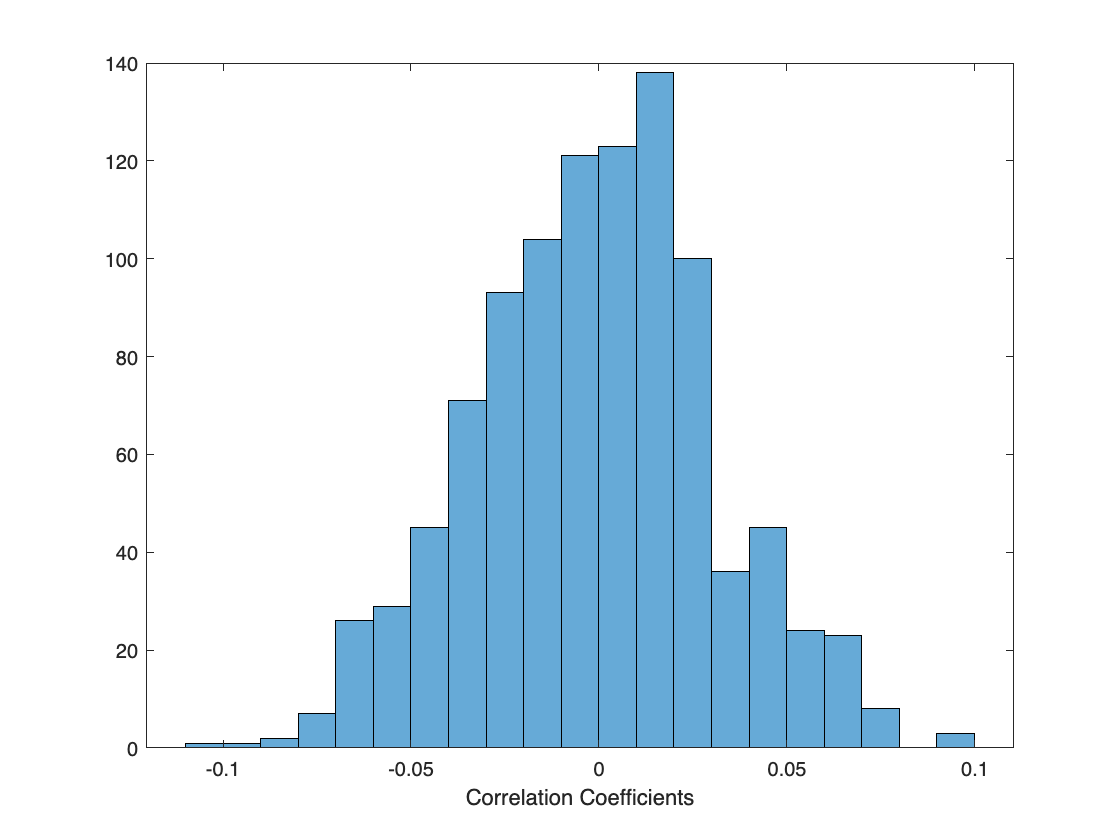

%This post-hoc power analysis is being performed to determine the number of
%data samples needed to achieve 80% power for a series of possible effect
%sizes

effect_size= [0.1, 0.2, 0.3, 0.4, 0.55, 0.6, 0.7 0.8, 0.9]; %Range of effect sizes

%Simulate LC spiking and pupil data distributions 
for i= 1:1000  
    poisson_data= poissrnd(100, [1000,1]);
    gaussian_data= normrnd(40, 100, [1000, 1]);
    corr_coef= corrcoef(poisson_data, gaussian_data);
    correlations(1, i)= corr_coef(1, 2);
end
histogram(correlations);
xlabel('Correlation Coefficients')

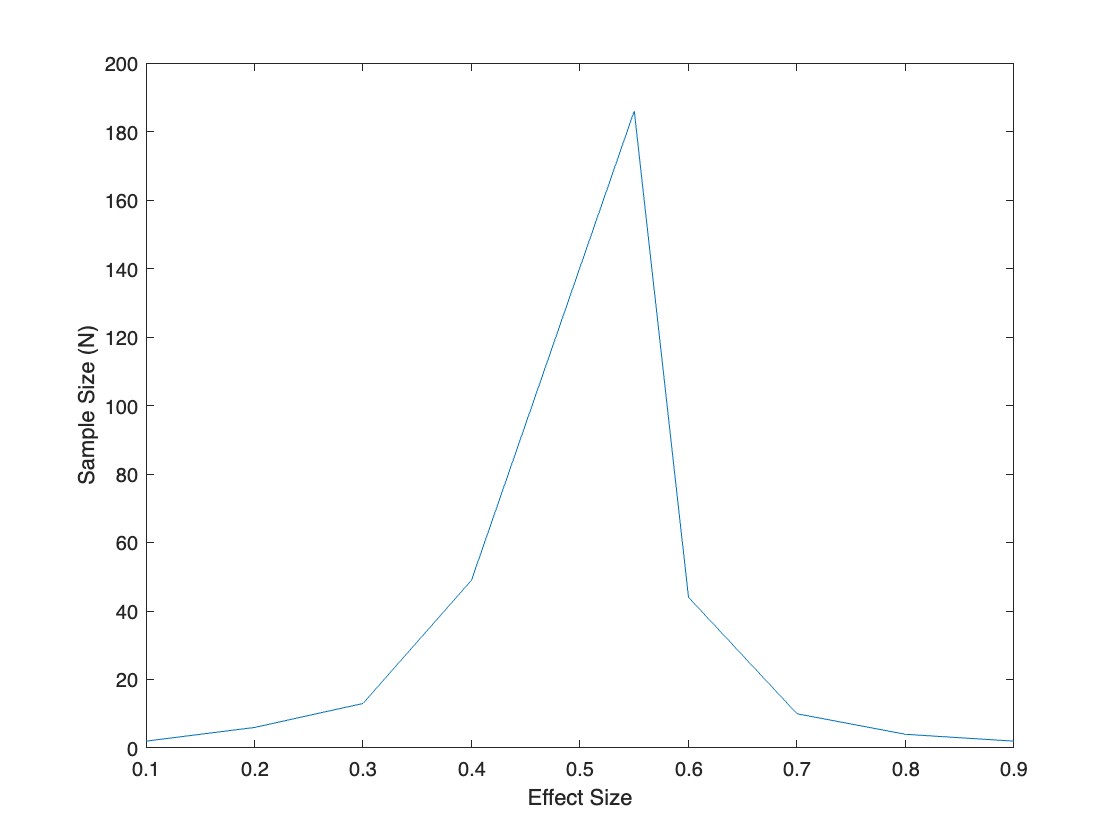

for f= 1:length(effect_size)
    p0= 1-effect_size(f);
    p1= effect_size(f);
    powers(1,f)= sampsizepwr("p",p0, p1, 0.8);
end
plot(effect_size, powers);
xlabel('Effect Size')
ylabel('Sample Size (N)')